clc 
clear
close all

MTOW_kg = 100; 
g = 9.81;
W = MTOW_kg * g;       
h = 0;                  
[~, ~, ~, rho] = atmosisa(h);
V_cruise = 30;      
ROC = 3;                
Sg = 80;               
n = 1.3;                
V_stall_req = 16;       
AR = 8;
e = 0.85;
k = 1 / (pi * AR * e);
CD0 = 0.025;
CL_max = 1.5;           
ita_p = 0.8;         
q_cruise = 0.5 * rho * V_cruise^2;

% Constraint Analysis 
WS = linspace(50, 1000, 500); % N/m^2

% Stall Limit
% W/S = 0.5 * rho * V_stall^2 * CL_max
WS_stall = 0.5 * rho * V_stall_req^2 * CL_max;

% Takeoff Constraint 
TW_to = (1.21 ./ (g * rho * CL_max * Sg)) .* WS;
V_lo = 1.1 * sqrt((2 .* WS) / (rho * CL_max)); 
PW_to = (TW_to .* (V_lo / sqrt(2))) / ita_p;

% Cruise Constraint (T = D)
TW_cruise = (q_cruise * CD0)./WS + (k/q_cruise).*WS;
PW_cruise = (TW_cruise .* V_cruise) / ita_p;

% Rate of Climb Constraint
% T/W = (ROC/V) + (q/WS)*CD0 + (k/q)*WS
TW_climb = (ROC / V_cruise) + (q_cruise * CD0)./WS + (k/q_cruise).*WS;
PW_climb = (TW_climb .* V_cruise) / ita_p;

% Sustained Turn Constraint
% T/W = q*[CD0/(W/S) + k*(n/q)^2 * (W/S)]
TW_turn = q_cruise * (CD0./WS + k * (n/q_cruise)^2 .* WS);
PW_turn = (TW_turn .* V_cruise) / ita_p;

% Service cieling Constraint
TW_sc = ROC/V_cruise + 2*sqrt(k*CD0/3);


% Design Point Selection
TW_req = [TW_to; TW_cruise; TW_climb; TW_turn];
TW_envelope = max(TW_req);

WS_design = WS_stall * 0.82; % 18% safety margin from stall
TW_design = interp1(WS, TW_envelope, WS_design);
PW_design = (TW_design * V_cruise) / ita_p;

% Results Calculation
S_required = W / WS_design;
Thrust_required = TW_design * W;
Power_required = (Thrust_required * V_cruise) / ita_p;

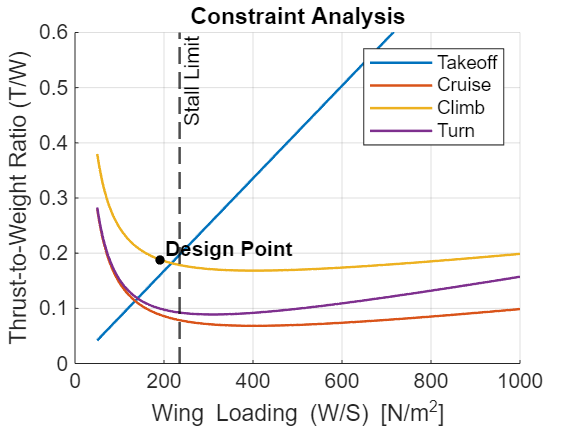

figure
hold on;

plot(WS, TW_to, 'LineWidth', 1.2);
plot(WS, TW_cruise, 'LineWidth', 1.2);
plot(WS, TW_climb, 'LineWidth', 1.2);
plot(WS, TW_turn, 'LineWidth', 1.2);
xline(WS_stall, '--k', 'Stall Limit', 'LineWidth', 1.2);

plot(WS_design, TW_design, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 4);
text(WS_design + 10, TW_design + 0.02, 'Design Point', 'FontWeight', 'bold');

grid on;
xlabel('Wing Loading (W/S) [N/m^2]');
ylabel('Thrust-to-Weight Ratio (T/W)');
title('Constraint Analysis');
legend('Takeoff', 'Cruise', 'Climb', 'Turn');
ylim([0 0.6]);
xlim([0 max(WS)]);
hold off;

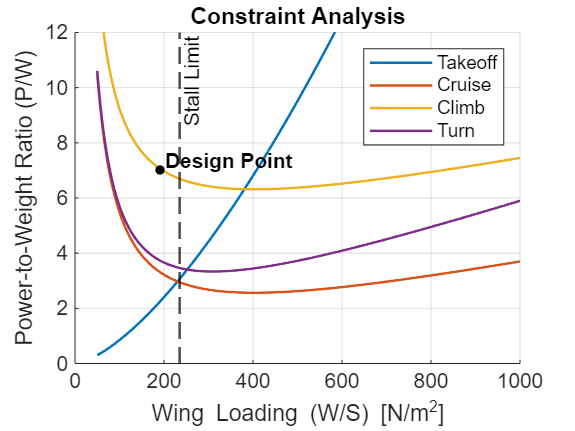



figure 
hold on
plot(WS, PW_to, 'LineWidth', 1.2);
plot(WS, PW_cruise, 'LineWidth', 1.2);
plot(WS, PW_climb, 'LineWidth', 1.2);
plot(WS, PW_turn, 'LineWidth', 1.2);
xline(WS_stall, '--k', 'Stall Limit', 'LineWidth', 1.2);

plot(WS_design, PW_design, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 4);
text(WS_design + 10, PW_design + 0.3, 'Design Point', 'FontWeight', 'bold');

grid on;
xlabel('Wing Loading (W/S) [N/m^2]');
ylabel('Power-to-Weight Ratio (P/W)');
title('Constraint Analysis');
legend('Takeoff', 'Cruise', 'Climb', 'Turn');
ylim([0 12]);
xlim([0 max(WS)]);
hold off;

fprintf('Wing Loading (W/S): %.2f N/m^2\n', WS_design);

Wing Loading (W/S): 192.86 N/m^2


fprintf('Thrust-to-Weight (T/W): %.3f\n', TW_design);

Thrust-to-Weight (T/W): 0.188


fprintf('Power-to-Weight (T/W): %.3f\n', PW_design);

Power-to-Weight (T/W): 7.044


fprintf('Required Wing Area: %.3f m^2\n', S_required);

Required Wing Area: 5.086 m^2


fprintf('Required Thrust: %.2f N\n', Thrust_required);

Required Thrust: 184.26 N


fprintf('Required Power: %.2f Watts\n', Power_required);

Required Power: 6909.92 Watts
